NodeTable = 100×4 table
    EndNodes    Xpoint    Ypoint       Layer   
    ________    ______    ______    ___________

    'IT'          27      4         internet   
    'C1'          23      3         core       
    'C2'          24      3         core       
    'C3'          25      3         core       
    'C4'          26      3         core       
    'C5'          27      3         core       
    'C6'          28      3         core       
    'C7'          29      3         core       
    'C8'          30      3         core       
    'C9'          31      3         core       
    'A1'        18.5      2         aggregation
    'A2'        19.5      2         aggregation
    'A3'        20.5      2         aggregation
    'A4'        21.5      2         aggregation
    'A5'        22.5      2         aggregation
    'A6'        23.5   

EdgeTable = 171×1 table
    EndNodes 
    _________

     1      2
     1      3
     1      4
     1      5
     1      6
     1      7
     1      8
     1      9
     1     10
    11      2
    11      3
    11      4
    12      5
    12      6
    12      7
    13      8
    13      9
    13     10
    14      2
    14      3
    14      4
    15      5
    15      6
    15      7
    16      8
    16      9
    16     10
    17      2
    17      3
    17      4
    18      5
    18      6
    18      7
    19      8
    19      9
    19     10
    20      2
    20      3
    20      4
    21      5
    21      6
    21      7
    22      8
    22      9
    22     10
    23      2
    23      3
    23      4
    24      5
    24      6
    24      7
    25      8
    25      9
    25     10
    26      2
    26      3
    26      4
    27      5
    27      6
    27      7
    28      8
    28      9
    28     10
    29     11
    29     12
   

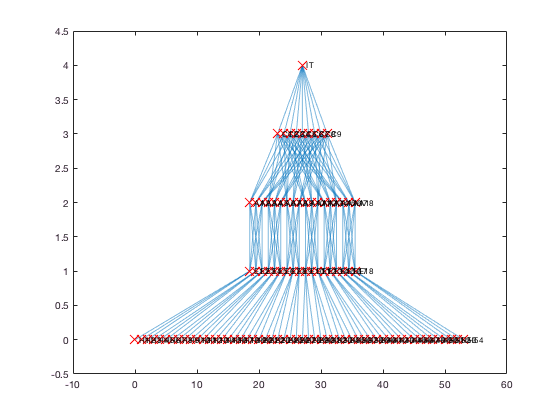

k=6;

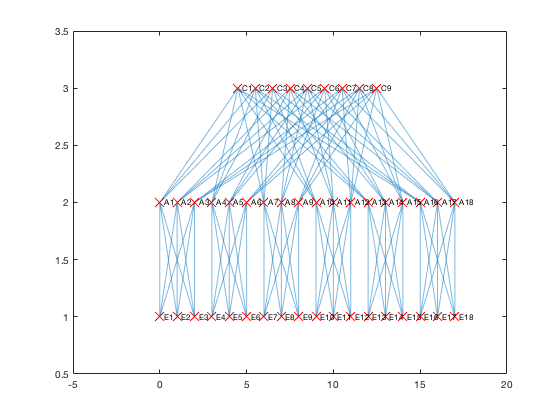

flaghosts=false;
flagit=false;

%Compute values for topology
assert(mod(k,2)==0,'Error, k must be an even number.')
core=(k/2)^2;
%pods=core/2;
aggregation=core*2;
%pods=k;
agg_to_core=k/2;%number of cores that an aggregation node connects to
ecm=k/2;%host per aggregation
posnode=0;
it=0;
variable_names_node_table = {'EndNodes';'Xpoint';'Ypoint';'Layer'};

%Compute values for plotting
differenceX=1;
%startX=0; Compute startX as the difference between total width and width of present layer divided by 2.
differenceY=1;
startY=4;
%width=aggregation*ecm*differenceX;
width=(aggregation-1)*differenceX;

%Preallocation
%TODO preallocate edges
if flagit
    it=1;
    posnode=it;
end
if ~flaghosts
    ecm=0;
end
h=aggregation*2+aggregation*ecm+core+posnode;
endnodes = cell(h, 1);
Xpoint(h,1)=1;
Ypoint(h,1)=1;
layern(h,1)=1;
edges(core*it+2*aggregation*agg_to_core+aggregation*ecm,2)=1;

%Internet layer
if flagit
    Xpoint(1,1)=width/2;
    Ypoint(1,1)=startY;
    layern(1)=0;
    endnodes{1}='IT';
end

%Ypoint=zeros(h,1)+ones(h-aggregation*host_per_aggregation,1)+ones(core+1+aggregation,1)+ones(core+1,1)+ones(1,1)

%Core layer
startX=(width-(core-1)*differenceX)/2;
startY=startY-differenceY;
for i=1:core
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    layern(posnode)=1;
    endnodes{posnode} = strcat('C', num2str(i));
    if flagit
    edges(i,1)= 1;
    edges(i,2)= i+1;
    end
end

%Aggregation layer
if flagit
    posedge=i;
else
    posedge=0;
end
startY=startY-differenceY;
startX=(width-(aggregation-1)*differenceX)/2;
countpod=1;
posagg=posnode;
for i=1:aggregation
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    layern(posnode,1)=2;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    endnodes{posnode} = strcat('A', num2str(i));
    if i>countpod*agg_to_core
        countpod=countpod+1;
    end
    addj=((i-(countpod-1)*agg_to_core)-1)*agg_to_core;
    for j=it+1:agg_to_core+it
        posedge=posedge+1;
        edges(posedge,1)=posnode;
        edges(posedge,2)= j+addj;
    end
end

%Edge layer
startY=startY-differenceY;
startX=(width-(aggregation-1)*differenceX)/2;
countpod=1;
for i=1:aggregation
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    layern(posnode,1)=3;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    endnodes{posnode} = strcat('E', num2str(i));
    if i>countpod*agg_to_core
        countpod=countpod+1;
    end
    addj=posagg+(countpod-1)*agg_to_core;
    for j=1:agg_to_core
        posedge=posedge+1;
        edges(posedge,1)=posnode;
        edges(posedge,2)= j+addj;
    end
end

%Host layer
if flaghosts
    posagg=posagg+aggregation;
    differenceX=width/(ecm*aggregation-1);
    startY=startY-differenceY;
    posnode1=posnode;
    count=1;
    count2=1;
    for j=1:aggregation
        addj=posnode1+(count2-1)*ecm;
        for i=1:ecm
            posnode=posnode+1;
            Ypoint(posnode,1)=startY;
            layern(posnode,1)=4;
            Xpoint(posnode,1)=startX+differenceX*(count-1);
            endnodes{posnode} = strcat('H', num2str(count));
            posedge=posedge+1;
            edges(posedge,1)=posagg+j;
            edges(posedge,2)=i+addj;
            count=count+1;
        end
        count2=count2+1;
    end
end

layer=categorical(layern,0:4,{'internet' 'core' 'aggregation' 'edge' 'host'});
NodeTable=table(endnodes,Xpoint,Ypoint,layer,'VariableNames',variable_names_node_table);
EdgeTable=table(edges,'VariableNames',{'EndNodes'});
G=graph(EdgeTable,NodeTable);
plotGraphtopology(G);